function env = generateEnvironment(actionInfo, mdl)
    obsInfo = rlNumericSpec([5 1]);    
    env = rlSimulinkEnv(mdl, mdl + "/Agent/RL Agent", obsInfo, actionInfo, 'UseFastRestart', 'on');    
    env.ResetFcn = @(in)MyResetFunction(in);
end

function pcmOP = storeReferencePoint(mdl)
    % save the operation point at the beginning of ABS braking
    simIn = Simulink.SimulationInput(mdl);
    simIn = setModelParameter(simIn,"SaveFinalState","on");
    simIn = setModelParameter(simIn,"SaveOperatingPoint","on");
    simIn = setModelParameter(simIn,"StopTime","11.7");
    simIn = setBlockParameter(simIn, mdl + "/Agent/StoppingCondition", Value="-100");
    out = sim(simIn);
    pcmOP = out.xFinal;
    save("PassCarModel_Final_OperationPoint.mat", "pcmOP");
end

% Fuzzing noise offset in the interval of 
FO_max = 50;
FO_min = 0;
% Fuzzing noise variation in the range of 
%FR_max = 20;  --> define for each scenario
FR_min = 0;

fr_max(1) = 20;
fr_max(2) = 0;
fr_max(3) = 20;
fr_max(4) = 0;

mu = [0.4 0.5 0.6 0.7 0.8];
swp = [450 475 500 525 550];
swp = swp*pi/180;


simIn = setBlockParameter(simIn, mdl + "/Agent/Policy/Fuzzing_wo_RL", Value="0");
simIn = setBlockParameter(simIn, mdl + "/Controllers and CAN network/Gateway/BC-Filter/FilterWheelSpeed/Switch_off_filter", Value="0");

load(agents(3));    
FR_max = fr_max(3);
Ts = ts_(3);
agent = saved_agent;
simOptions = rlSimulationOptions(MaxSteps=500);    
agent.UseExplorationPolicy = false;    
env = generateEnvironment(actionInfo(3), mdl);
storeReferencePoint(mdl);

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.2171s



for i=1:5
    for j=1:5
        set_param(mdl + "/Vehicle with driver and environment/Driver/Evasion/SteeringWheelPosition", "Value", sprintf("%f", swp(i)));
        set_param(mdl + "/Vehicle with driver and environment/Environment/Road Track Friction", "lambda_g", sprintf("%f", mu(j)));
        gridSimOutput(i,j) = sim(env, agent, simOptions);
    end
end

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.91063s
### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.90165s
### Searching for referenced models in mod

set_param(mdl + "/Vehicle with driver and environment/Driver/Evasion/SteeringWheelPosition", "Value", "500*pi/180");
set_param(mdl + "/Vehicle with driver and environment/Environment/Road Track Friction", "lambda_g", "0.6");

pcmOP = storeReferencePoint(mdl);
simIn = Simulink.SimulationInput(mdl);
simIn = simIn.setInitialState(pcmOP);
simIn = setBlockParameter(simIn, mdl + "/Agent/Policy/Fuzzing", Value="0");
for i=1:5
    for j=1:5
        set_param(mdl + "/Vehicle with driver and environment/Driver/Evasion/SteeringWheelPosition", "Value", sprintf("%f", swp(i)));
        set_param(mdl + "/Vehicle with driver and environment/Environment/Road Track Friction", "lambda_g", sprintf("%f", mu(j)));
        baseLineGridSimOutput(i,j) = sim(simIn, UseFastRestart="on");
    end
end
set_param(mdl + "/Vehicle with driver and environment/Driver/Evasion/SteeringWheelPosition", "Value", "500*pi/180");
set_param(mdl + "/Vehicle with driver and environment/Environment/Road Track Friction", "lambda_g", "0.6");

x_min = min(timeseries2timetable(gridSimOutput(1, 1).SimulationInfo(1).logsout.getElement("AvgLatAcc").Values).Time);
x_max = max(timeseries2timetable(gridSimOutput(1, 1).SimulationInfo(1).logsout.getElement("AvgLatAcc").Values).Time);

if min(timeseries2timetable(baseLineGridSimOutput(1, 1).logsout.getElement("AvgLatAcc").Values).Time) < x_min
    x_min = min(timeseries2timetable(baseLineGridSimOutput(1, 1).logsout.getElement("AvgLatAcc").Values).Time);
end
if max(timeseries2timetable(baseLineGridSimOutput(1, 1).logsout.getElement("AvgLatAcc").Values).Time) > x_max
    x_max = max(timeseries2timetable(baseLineGridSimOutput(1, 1).logsout.getElement("AvgLatAcc").Values).Time);
end

for i=1:5
    for j=1:5
        if min(timeseries2timetable(baseLineGridSimOutput(i, j).logsout.getElement("AvgLatAcc").Values).Time) < x_min
            x_min = min(timeseries2timetable(baseLineGridSimOutput(i, j).logsout.getElement("AvgLatAcc").Values).Time);
        end
        if max(timeseries2timetable(baseLineGridSimOutput(i, j).logsout.getElement("AvgLatAcc").Values).Time) > x_max
            x_max = max(timeseries2timetable(baseLineGridSimOutput(i, j).logsout.getElement("AvgLatAcc").Values).Time);
        end
    end
end

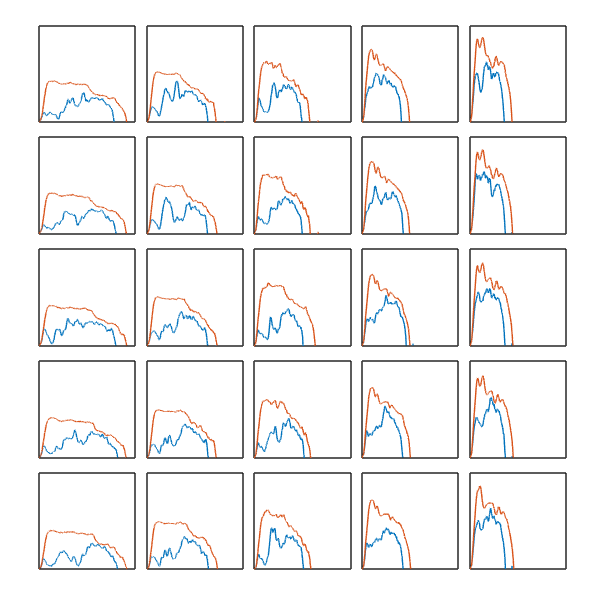


tiledlayout(5, 5, 'Padding', 'compact', 'TileSpacing', 'compact');

for i=1:5
    for j=1:5
        nexttile;
        ala = timeseries2timetable(gridSimOutput(i, j).SimulationInfo(1).logsout.getElement("AvgLatAcc").Values);
        ala_ref = timeseries2timetable(baseLineGridSimOutput(i, j).logsout.getElement("AvgLatAcc").Values);
        plot(ala.Time, ala{:,1});
        hold on;
        plot(ala_ref.Time, ala_ref{:,1});
        hold off;
        ylim([0 0.6]);
        xlim([x_min x_max]);
        axis square;    
        
        % Remove x and y ticks
        xticks([]);
        yticks([]);
        
        % Remove x and y axis labels
        xlabel('');
        ylabel('');
    end
end
set(gcf, 'Position', [100, 100, 600, 600]);  % [left, bottom, width, height]
f = gcf;
exportgraphics(f, 'AgentPerformanceGrid.pdf', 'ContentType', 'vector');